# Routh-Hurwitz Stability Criterion: Applications

## Exercise 1

`[Extract from: Written examination test of September, 12, 2022]`

Consider the polynomial equation


$$s^3+\big(2K-3\big)\,s^2-\big(5+2K\big)\,s+\big(K+3\big)=0 \quad K \in \mathbb{R}\,,\; s \in \mathbb{C} \quad (+)$$


Are there values of the real parameter $K$ such that the **roots** of the polynomial in $s$ all have **real** **parts less than** $-1$? 


$$\exists \bar K \in \mathbb{R}: \left\{\tilde{s} \in \mathbb{C}:\;p\left(\tilde{s},\;\bar{K}\right) =0 \right\} \,\stackrel{?}{\Rightarrow} \text{Re}\left(\tilde s\right) <-1$$


**Hint**: If $w = s + 1$ then it holds that 


$$\text{Re}\left(s) <-1 \,\Rightarrow \, \text{Re}\left(w\right) < \cdots$$


### Solution

In fact


$$w = s+1 \; \Longrightarrow \; \text{Re}(s)=\text{Re}(w)-1$$


thus


$$\text{Re}(s)<-1 \Longrightarrow \text{Re}(w) <0$$


**Idea**: let's substitute the variable $s$ with the expression $s=w-1$in the polynomial expression $(+)$ and then apply the Routh-Hurwitz criterion on the new polynomial 

clear
syms s w 
syms K real
p(s, K) = s^3 +(2*K-3)*s^2 -(5+2*K)*s +(K+3)

$$p(s, K) = s^{3}+\left(2\,K-3\right)\,s^{2}+\left(-2\,K-5\right)\,s+K+3$$


% now substitute the expression using w
q(w, K ) = expand(subs(p,s , w-1)) 

$$q(w, K) = 5\,K+4\,w-6\,K\,w+2\,K\,w^{2}-6\,w^{2}+w^{3}+4$$

q(w, K ) = collect(q, w)

$$q(w, K) = w^{3}+\left(2\,K-6\right)\,w^{2}+\left(4-6\,K\right)\,w+5\,K+4$$

Now, let's build the **Routh table**


$$\begin{array}{c|cc}
3 & 1  & 2\big(2-3\,K\big) \\
2 & 2 \big(K-3\big) & \big(5\,K+4\big)\\
1 & \alpha \\
0 & \big(5\,K+4\big)
\end{array} \qquad 
\alpha = -\frac{1}{2 \big(K-3\big)}
 \left\vert \begin{array}{cc}
1  & 2\big(2-3\,K\big) \\
2 \big(K-3\big) & \big(5\,K+4\big)
\end{array} \right\vert$$


alpha = simplify(-(1/(2*(K-3)))*det([1 2*(2-3*K); 2*(K-3)  (5*K+4)]))

$$alpha = -\frac{12\,K^{2}-39\,K+28}{2\,\left(K-3\right)}$$

Now the table is complete


$$\begin{array}{c|cc}
3 & 1  & 2\big(2-3\,K\big) \\
2 & 2 \big(K-3\big) & \big(5\,K+4\big)\\
1 & -\frac{12\,K^2-39K +28}{2(K-3)}\\
0 & \big(5\,K+4\big)
\end{array} $$


To ensure that the roots of the polynomial $q(w)$ have a negative real part, the elements in the first column of the table MUST ALL have the same sign (positive, because the first term is $+1$).

Thus


$$\left\{ \begin{array}{rcl}
2\left(K-3\right) &>& 0\\
-\left(12K^2-39K+28\right) &>& 0\\
5K+4 &>&0
\end{array} \right. \quad \Longrightarrow \quad 
\left\{ \begin{array}{rcl}
K &>& +3\\
\left(12K^2-39K+28\right) &<& 0\\
K &>&-\frac{4}{5}
\end{array} \right. $$


p_auxK = 12*K^2-39*K+28;
Kaux = simplify(solve(p_auxK))

$$Kaux = \left[\begin{array}{c} \frac{13}{8}-\frac{\sqrt{177}}{24}\\ \frac{\sqrt{177}}{24}+\frac{13}{8} \end{array}\right]$$

K1 = vpa(Kaux(1)); K2 = vpa(Kaux(2)); 
% to have a floating point representation of both K1 and K2

In the end


$$\left\{ \begin{array}{rcl}
K &>& +3\\
\frac{13}{8}-\frac{\sqrt{177}}{24} &< K <& \frac{13}{8}+\frac{\sqrt{177}}{24}\\
K &>&-\frac{4}{5}
\end{array} \right. $$


sort([K1, (-4/5)], 'ascend') % let's compare K1 and (-4/5)

$$ans = \left[\begin{array}{cc} -\frac{4}{5} & 1.0706610543479137197897487160782 \end{array}\right]$$

sort([K2, (+3)], 'ascend')  % let's compare K2 and (+3)

$$ans = \left[\begin{array}{cc} 2.1793389456520862802102512839218 & 3 \end{array}\right]$$

It is clear that **there is no solution**!

## Exercise 2

Consider the polynomial equation


$$s^3+\big(2K-3\big)\,s^2+\big(5+2K\big)\,s+\big(K+3\big)=0 \quad K \in \mathbb{R}\,,\; s \in \mathbb{C} \quad (++)$$


Are there values of the real parameter $K$ such that the **roots** of the polynomial in $s$ all have **real** **parts** **greater than** $-2$? 


$$\exists \bar K \in \mathbb{R}: \left\{\tilde{s} \in \mathbb{C}:\;p\left(\tilde{s},\;\bar{K}\right) =0 \right\} \,\stackrel{?}{\Rightarrow} \text{Re}\left(\tilde s\right) >-2$$


**Hint**: If $w = s +2$ then it holds that 


$$\text{Re}\left(s) >-2 \,\Rightarrow \, \text{Re}\left(w\right) >\cdots$$


### Solution

In fact


$$w = s+2 \; \Longrightarrow \; \text{Re}(s)=\text{Re}(w)-2$$


thus


$$\text{Re}(s)>-2 \Longrightarrow \text{Re}(w) >0$$


**Idea**: let's substitute the variable $s$ with the expression $s=w-2$in the polynomial expression $(++)$ and then apply the Routh-Hurwitz criterion on the new polynomial 

clear
syms s w 
syms K real
p(s, K) = s^3 +(2*K-3)*s^2 -(5+2*K)*s +(K+3)

$$p(s, K) = s^{3}+\left(2\,K-3\right)\,s^{2}+\left(-2\,K-5\right)\,s+K+3$$


% now substitute the expression using w
q(w, K ) = expand(subs(p,s , w-2)) 

$$q(w, K) = 13\,K+19\,w-10\,K\,w+2\,K\,w^{2}-9\,w^{2}+w^{3}-7$$

q(w, K ) = collect(q, w)

$$q(w, K) = w^{3}+\left(2\,K-9\right)\,w^{2}+\left(19-10\,K\right)\,w+13\,K-7$$

Now, let's build the **Routh table**


$$\begin{array}{c|cc}
3 & 1  & 19-10\,K \\
2 & 2 K-9&13\,K-7\\
1 & \alpha \\
0 & 13\,K-7
\end{array} \qquad 
\alpha = -\frac{1}{2 K-9}
 \left\vert \begin{array}{cc}
1  & 19-10\,K \\
2 K-9 & 13\,K-7
\end{array} \right\vert$$


alpha = simplify(-(1/(2*K-9))*det([1 (19-10*K); (2*K-9)  (13*K-7)]))

$$alpha = -\frac{20\,K^{2}-115\,K+164}{2\,K-9}$$

Now the table is complete


$$\begin{array}{c|cc}
3 & 1  & 19-10\,K \\
2 & 2 K-9&13\,K-7\\
1 & -\frac{20\,K^2-115\,K+164}{2\,K-9}\\
0 & 13\,K-7
\end{array} $$


To ensure that the roots of the polynomial $q(w)$ have a positive real part, the **elements** in the first column of the table MUST have **alternate signs** (positive, negative, positive and negative - the first term is positive).

Thus


$$\left\{ \begin{array}{rcl}
2\,K-9 &<& 0\\
-\left(20\,K^2-115\,K+164\right) &<& 0\\
13\,K-7 &<&0
\end{array} \right. \quad \Longrightarrow \quad 
\left\{ \begin{array}{rcl}
K &<& \frac{9}{2}\\
\left(20\,K^2-115\,K+164\right) &>& 0\\
K &<&\frac{7}{13}
\end{array} \right. $$


p_auxK = 20*K^2-115*K+164;
Kaux = simplify(solve(p_auxK))

$$Kaux = \left[\begin{array}{c} \frac{23}{8}-\frac{\sqrt{105}}{40}\\ \frac{\sqrt{105}}{40}+\frac{23}{8} \end{array}\right]$$

K1 = vpa(Kaux(1)); K2 = vpa(Kaux(2));
% to have a floating point representation of both K1 and K2

In the end


$$\left\{ \begin{array}{rcl}
K &<& \frac{9}{2}\\
K < \frac{23}{8}-\frac{\sqrt{105}}{40} & , & K> \frac{23}{8}+\frac{\sqrt{105}}{40} \\
K &<&\frac{7}{13}
\end{array} \right. $$


sort([9/2; K1; K2; 7/13], 'ascend') % let's compare K1, K2 and the other values

$$ans = \left[\begin{array}{c} \frac{7}{13}\\ 2.618826230851010040419474032987\\ 3.131173769148989959580525967013\\ \frac{9}{2} \end{array}\right]$$

It is clear that **there is solution for **$K < \frac{7}{13}$.

disp(7/13)

    0.5385


For example $K = \frac{1}{4}$

p1(s) = subs(p,K, 1/4)

$$p1(s) = s^{3}-\frac{5\,s^{2}}{2}-\frac{11\,s}{2}+\frac{13}{4}$$

rootP = solve(p1,s)

$$rootP = \left[\begin{array}{c} \frac{1}{2}\\ 1-\frac{\sqrt{2}\,\sqrt{15}}{2}\\ \frac{\sqrt{2}\,\sqrt{15}}{2}+1 \end{array}\right]$$

(real(rootP)>-2)

$$ans = \left[\begin{array}{c} -2<\frac{1}{2}\\ -2<1-\frac{\sqrt{2}\,\sqrt{15}}{2}\\ -2<\frac{\sqrt{2}\,\sqrt{15}}{2}+1 \end{array}\right]$$

## Exercise 3

Consider the LTI system described by the block diagram

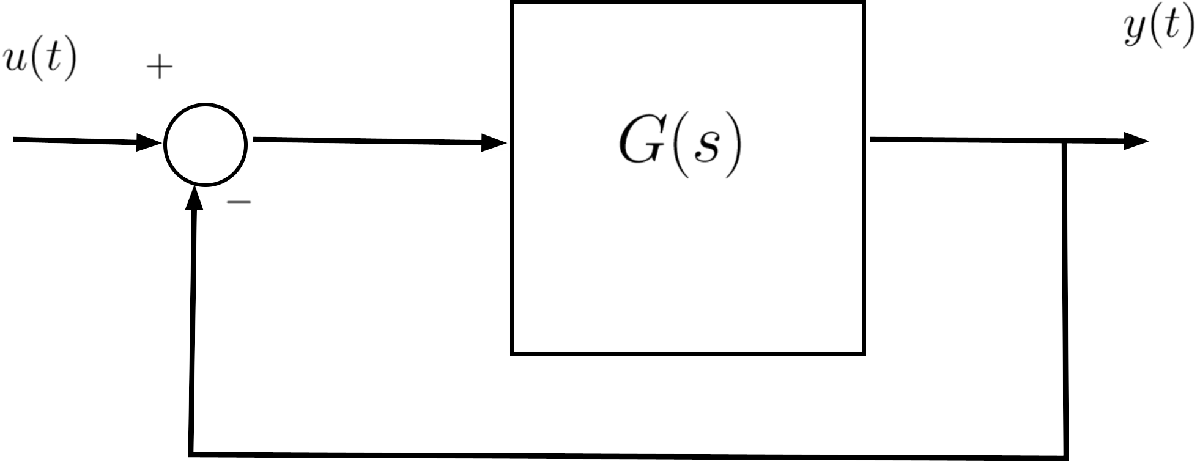

where


$$G(s) = k\cdot \frac{\left(1-\frac{s}{2}\right)}{\left(1+\frac{s}{50}\right)\big(1+s\big)}\;,\quad k \ge 0$$


Are there values of the real parameter $k$ such that the **roots** of the **closed-loop polynomial** in $s$ all have **real** **parts less than** $-1$? 


$$\exists \bar k \in \mathbb{R}: \left\{\tilde{s} \in \mathbb{C}:\;p\left(\tilde{s},\;\bar{k}\right) =0 \right\} \,\stackrel{?}{\Rightarrow} \text{Re}\left(\tilde s\right) <-1$$


**Hint**: If $w = s + 1$ then it holds that 


$$\text{Re}\left(s) <-1 \,\Rightarrow \, \text{Re}\left(w\right) < \cdots$$


### Solution

In fact


$$w = s+1 \; \Longrightarrow \; \text{Re}(s)=\text{Re}(w)-1$$


thus


$$\text{Re}(s)<-1 \Longrightarrow \text{Re}(w) <0$$


The closed-loop polynomial is


$$p(s) = \left(1+\frac{s}{50}\right)\big(1+s\big) + k\left(1-\frac{s}{2}\right)\;,\quad k \in \mathbb{R} \quad (\star)$$


clear
syms s k w
p(s,k) = (1+s/50)*(1+s)+k*(1-s/2)

$$p(s, k) = \left(\frac{s}{50}+1\right)\,\left(s+1\right)-k\,\left(\frac{s}{2}-1\right)$$

p(s,k) = collect(p,s)

$$p(s, k) = \frac{s^{2}}{50}+\left(\frac{51}{50}-\frac{k}{2}\right)\,s+k+1$$


% now substitute the expression using w
q(w, k ) = expand(subs(p,s , w-1)) 

$$q(w, k) = \frac{3\,k}{2}+\frac{49\,w}{50}-\frac{k\,w}{2}+\frac{w^{2}}{50}$$

q(w, k ) = collect(q, w)

$$q(w, k) = \frac{w^{2}}{50}+\left(\frac{49}{50}-\frac{k}{2}\right)\,w+\frac{3\,k}{2}$$

Now, let's build the **Routh table**


$$\begin{array}{c|cc}
2 & \frac{1}{50} &\frac{3k}{2}\\
1& \left(\frac{49}{50}-\frac{k}{2}\right)\\
0& \frac{3k}{2}
\end{array}$$


To ensure that the roots of the polynomial $q(w)$ have a negative real part, the elements in the first column of the table MUST ALL have the same sign (positive, because the first term is $+1/50$).

Thus


$$\left\{ \begin{array}{rcl}
\frac{49}{50}-\frac{k}{2} &>& 0\\
\frac{3k}{2} &>&0
\end{array} \right. \quad \Longrightarrow \quad
\left\{ \begin{array}{rcl}
k &<& \frac{49}{25} \\
k &>& 0
\end{array} \right. \quad \Longrightarrow \quad 0<k<\frac{49}{25}$$


disp(49/25)

    1.9600


For example, let's choose $k= 1.5$

p1(s) = subs(p,k,1.5)

$$p1(s) = \frac{s^{2}}{50}+\frac{27\,s}{100}+\frac{5}{2}$$


p1_roots = solve(p1,s)

$$p1\_roots = \left[\begin{array}{c} -\frac{27}{4}-\frac{\sqrt{1271}\,\mathrm{i}}{4}\\ -\frac{27}{4}+\frac{\sqrt{1271}\,\mathrm{i}}{4} \end{array}\right]$$

Let's check the real part of the roots

(real(p1_roots)<-1)

$$ans = \left[\begin{array}{c} -\frac{27}{4}<-1\\ -\frac{27}{4}<-1 \end{array}\right]$$

#### A Particular Configuration

What if $k=\frac{49}{25}$?

The Routh table of the polynomial $q(w,k)$ becomes


$$\begin{array}{c|cc}
2 & \frac{1}{50} &\frac{3k}{2}\\
1&0\\
0& \frac{3k}{2}
\end{array}$$


i.e., the polynomial itself becomes 


$$q(w) = \frac{1}{50}\,w^2+\frac{147}{50} = \frac{1}{50}\,\left(w-j\sqrt{147}\right)\,\left(w+j\sqrt{147}\right)$$


Analysing the original polynomial $p(s)$, this result allows us to state that $p(s)$ admits two conjugate complex roots with real parts equal to $-1$: 

p2(s) = subs(p,k,49/25)

$$p2(s) = \frac{s^{2}}{50}+\frac{s}{25}+\frac{74}{25}$$

p2roots = solve(p2,s)

$$p2roots = \left[\begin{array}{c} -1-7\,\sqrt{3}\,\mathrm{i}\\ -1+7\,\sqrt{3}\,\mathrm{i} \end{array}\right]$$

### Exploring the Roots Locus

Consider the closed-loop polynomial in Eq. $(\star)$:


$$p(s) = \left(1+\frac{s}{50}\right)\big(1+s\big) + k\left(1-\frac{s}{2}\right)\;,\quad k \in \mathbb{R}$$


What happens at the poles of the system when k varies? Do they shift? How?

- Generate a set of $1000$ different values, linearly spaced,  for the free parameter  $k$ in the interval $\left[\frac{1}{10000}\,,\quad 100\right]$

- For each value of $k$ (starting with the smallest and ending with the largest), evaluate the roots of the polynopmial $p(s)$, i.e. the poles of the closed-loop LTI system, and store them in a numeric array named **poles_G as complex values**.

- Create a figure and plot the eigenvalues in **poles_G **using the following style: plot each pole as an point in the complex plane ℂ, so use the real part and the imaginary part of every pole as coordinate in the plot: `plot(real(x), imag(x))` where x is a pole.

- Moreover, use a green mark 'x' for the poles corresponding to the smallest value of $k$ and a red mark 'x' for the poles corresponding to the largest value of $k$. Use a blue mark 'x' for the remaining poles. 

clear
syms s k 
p(s,k) = (1+s/50)*(1+s)+k*(1-s/2)

$$p(s, k) = \left(\frac{s}{50}+1\right)\,\left(s+1\right)-k\,\left(\frac{s}{2}-1\right)$$

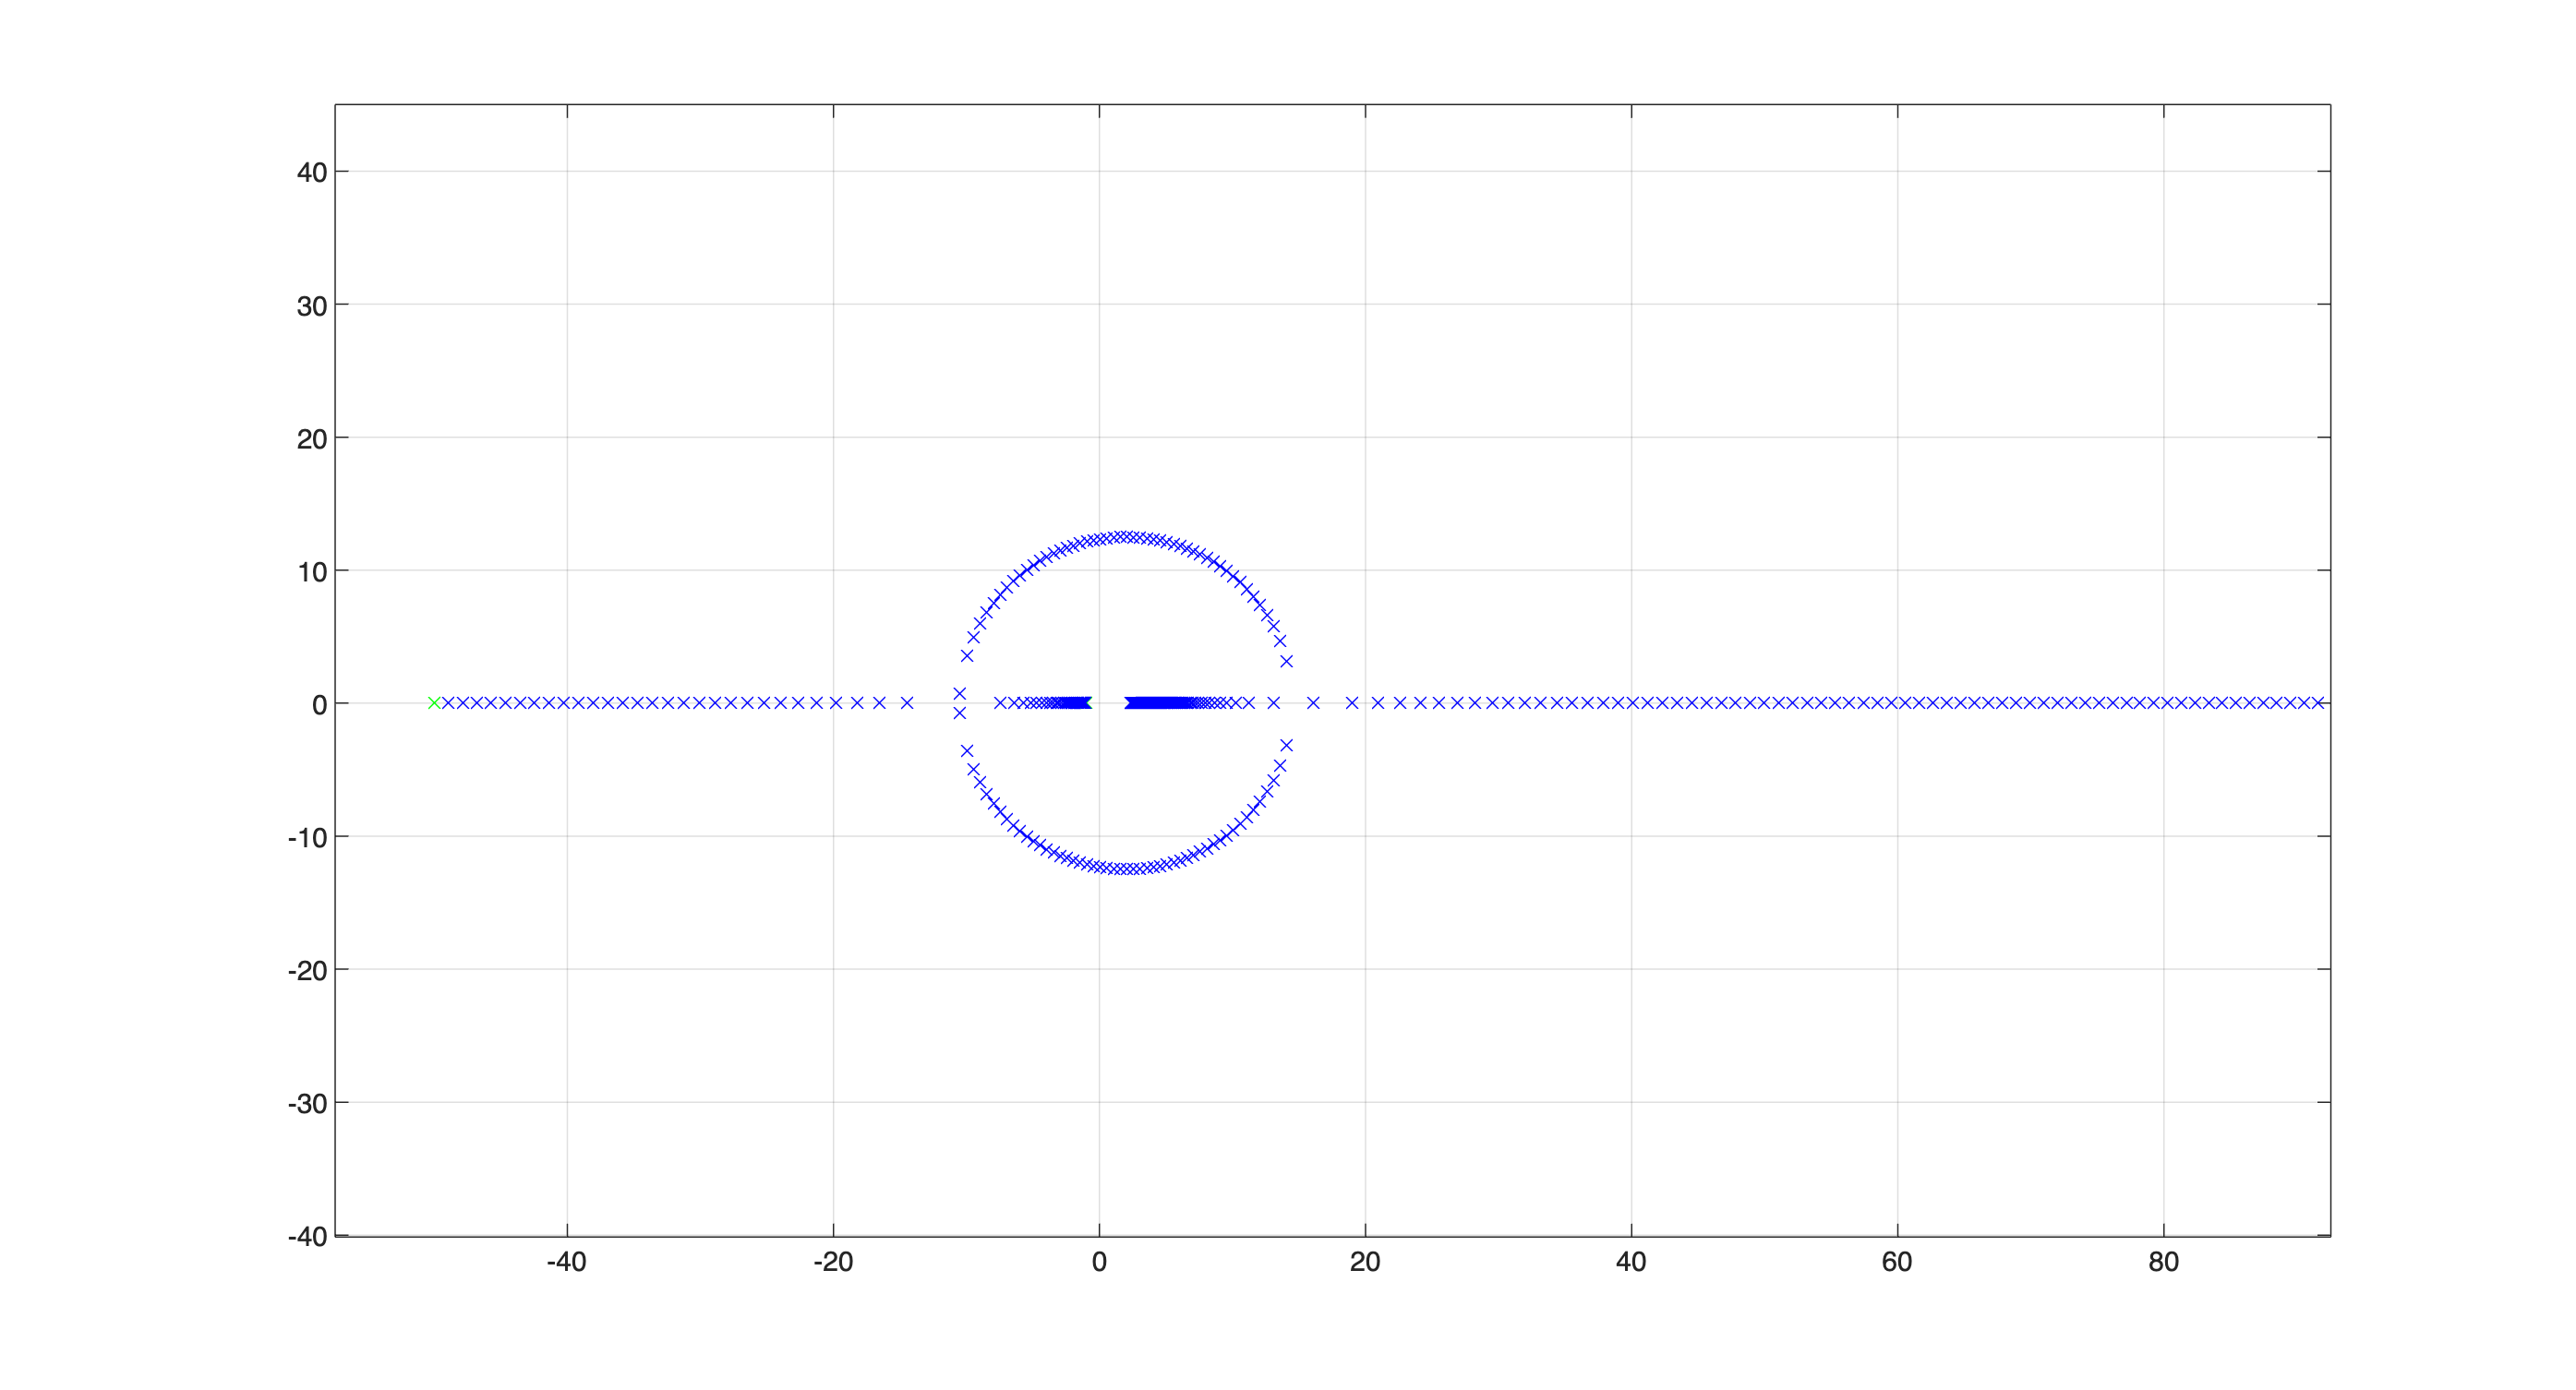


N_k = 500; % how many values for the parameter k?

N_p = polynomialDegree(p,s); 
% the degree of p( ) with respect to the variable 's' <--> how many poles for each value of the parameter k

k_val = linspace(0,20, N_k);
poles_G = zeros(N_p, N_k);

for n = 1:N_k
    kV = k_val(n);
    currClosedloopPOLY = subs(p, k, kV); % let's substitute the actual value for k
    currPOLY_ROOTS = solve(currClosedloopPOLY); % computing the roots
    for a = 1: N_p
        dummyP  = double(currPOLY_ROOTS(a));
        poles_G(a,n) = complex(dummyP); % storing the poles
    end % for a
end % for n

% the approximated roots locus
figure('Units','normalized', 'Position',[0.1, 0.1, 0.99, 0.95]) % to use almost all the room at disposal

% initial and ending posittions of the poles
for k = 1:2
    plot(real(poles_G(k,1)), imag(poles_G(k,1)), 'gx');
    hold on
    plot(real(poles_G(k,N_k)), imag(poles_G(k,N_k)), 'rx');
end % for k

% every other position for the poles
for k = 1:2
    for n = 2:N_k-1
        plot(real(poles_G(k,n)), imag(poles_G(k,n)), 'bx');
    end % for n
end % for k
grid on; zoom on;
xlim([-60, +100])
axis equal